clear

orig_mesh = 't_05_no_bl_80'

orig_mesh = 't_05_no_bl_80'

displayplots = true;
include_angles = true;
cutplane = 'XZ';

addpath('..\..\..\utilities');
nodepos = load(fullfile('..\input', orig_mesh, 'Np.mat')).Np;
shearrates = load(fullfile('..\input', orig_mesh, 'Shearrate.mat')).SRnode;
shearrates(shearrates(:, :) == -1e+30) = 0;
temps = load(fullfile('..\input', orig_mesh, 'Tnode.mat')).Tnode;
fillstatus = load(fullfile('..\input', orig_mesh, 'Fillstatus.mat')).Fillstatus;
connectednodes = load(fullfile('..\input', orig_mesh, 'connectedNodes.mat')).connectedNodes;
connectedelements = load(fullfile('..\input', orig_mesh, 'connectedElements.mat')).connectedElements;
velx = load(fullfile('..\input', orig_mesh, 'VelX.mat')).VelX;
vely = load(fullfile('..\input', orig_mesh, 'VelY.mat')).VelY;
velz = load(fullfile('..\input', orig_mesh, 'VelZ.mat')).VelZ;
viscs = load(fullfile('..\input', orig_mesh, 'Visc.mat')).Visc;
viscs(viscs(:, :) == -1e+30) = 0;

meshrefiner = meshRefiner;
easyvisualizer = easyVisualizer;
udmwriter = udmWriter;

logs_dir_name = fullfile('..\output', orig_mesh);
if ~exist(logs_dir_name, 'dir')
    mkdir(logs_dir_name);
end

% Neccesary element information for further refinement and plotting
elementnodeids = connectednodes + 1; % +1 so that indexing will work
elementnodesfilled = meshrefiner.getElementValues(elementnodeids, fillstatus);
elementfillstatus = meshrefiner.calcElementFillstatus(elementnodesfilled);
elementcoordinates = easyvisualizer.getElementCoordinates(elementnodeids, nodepos);

% Getting element values for all the investigated values
elementshearrates = meshrefiner.getElementValues(elementnodeids, shearrates);
elementtemps = meshrefiner.getElementValues(elementnodeids, temps);
[elementvellen, angle_deg] = meshrefiner.calcElementVelocities(elementnodeids, velx, vely, velz);
elementviscs = meshrefiner.getElementValues(elementnodeids, viscs);

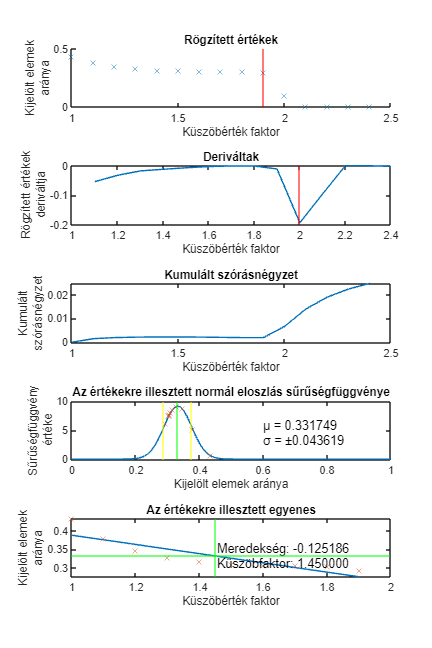

% Calculating diffs and highdiffelements
vellendiffs_rr = meshrefiner.calcElementDiffs(elementvellen, 'relrange');
[highvellendiffs_rr, normalvellendiffs_rr, highvellendiffsbytimestep_rr, ideal_threshold_vellen_rr, slope_vellen_rr, s_vellen_rr, frac_vellen_rr, ctpn_vellen_rr, fig_vellen_rr] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, vellendiffs_rr, false, true, displayplots, 0.1, 10);

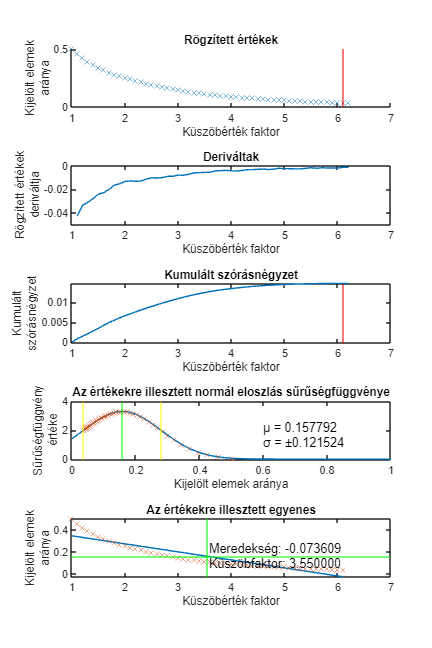

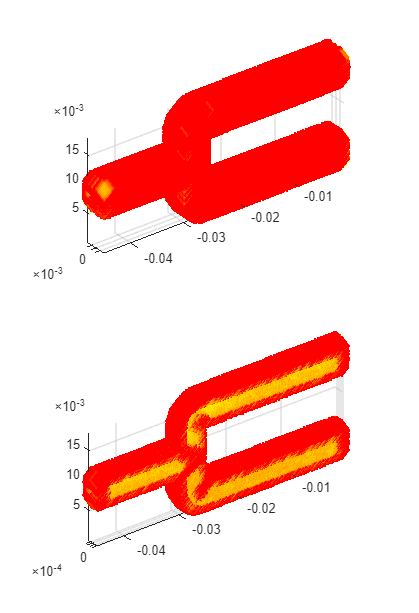


if include_angles == true
    anglediffs_r = meshrefiner.calcElementDiffs(angle_deg, 'range');
    [highanglediffs_r, normalanglediffs_r, highanglediffsbytimestep_r, ideal_threshold_angle_r, slope_angle_r, s_angle_r, frac_angle_r, ctpn_angle_r, fig_angle_r] = meshrefiner.calcHighDiffElementsAutoThreshold(elementfillstatus, anglediffs_r, false, true, displayplots, 0.1, 10);
    highveldiffs = union(highvellendiffs_rr(:, 1), highanglediffs_r(:, 1));
    normalveldiffs = intersect(normalvellendiffs_rr, normalanglediffs_r);
    pic_ = easyvisualizer.plotElementsToRefine(elementcoordinates, highveldiffs, normalveldiffs, 0, cutplane, displayplots);
    print(pic_, fullfile('../output', orig_mesh, strcat(orig_mesh, '_multinode_.png')), '-dpng');
else
    highveldiffs = highvellendiffs_rr;
    normalveldiffs = normalvellendiffs_rr;
end


tic
[newnodepos, newelementnodeids, affectedelements] = meshrefiner.createNewMeshMultiNode(nodepos, elementnodeids, highveldiffs);
toc

Elapsed time is 587.140624 seconds.


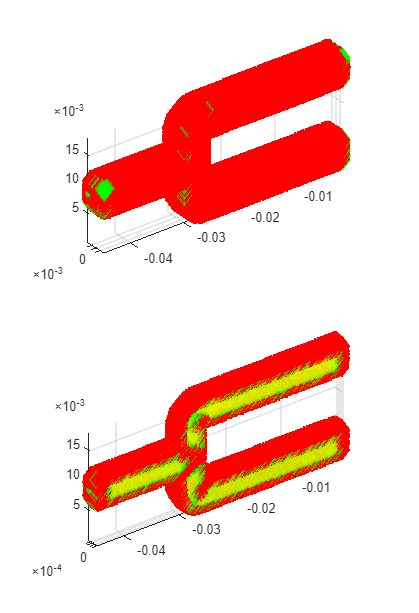

pic = easyvisualizer.plotElementsToRefine(elementcoordinates, highveldiffs, normalveldiffs, affectedelements, cutplane, displayplots);
print(pic, fullfile('../output', orig_mesh, strcat(orig_mesh, '_multinode.png')), '-dpng');

tic
udmwriter.createUDM(newnodepos, newelementnodeids, fullfile('../output', orig_mesh, strcat(orig_mesh, '_multinode.udm')));
toc

Elapsed time is 60.504857 seconds.


tic
[newnodepos_2, newelementnodeids_2] = meshrefiner.createNewMeshOneNode(highveldiffs, shearrates, elementnodeids, nodepos, false);
toc

Elapsed time is 65.464499 seconds.


tic
udmwriter.createUDM(newnodepos_2, newelementnodeids_2, fullfile('../output', orig_mesh, strcat(orig_mesh, '_onenode.udm')));
toc

Elapsed time is 28.622926 seconds.
